wpts = [0 45 15 90 45; 90 45 -45 15 90; 45 -45 90 15 90];

Compute the trajectory for a given number of samples (501). The function outputs the trajectory positions (`q`), velocity (`qd`), acceleration (`qdd`), time vector (`tvec`), and polynomial coefficients (`pp`) of the polynomial that achieves the waypoints using trapezoidal velocities.

[q,qd,qdd,tvec,pp] = lspbTrajectory(wpts,100);

Plot the trajectories for the *x- *and *y*-positions and the trapezoidal velocity profile between each waypoint.

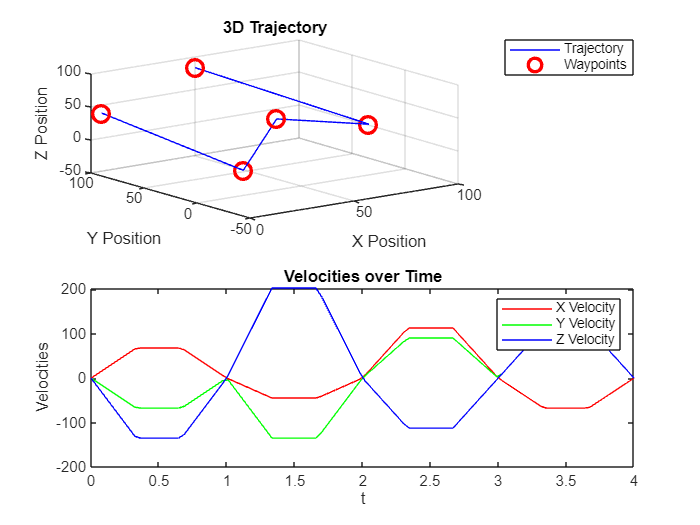

% Giả sử q, qd, tvec và wpts đã được định nghĩa và chứa dữ liệu

% Tạo hình 3D để vẽ quỹ đạo và tốc độ
figure;

% Vẽ quỹ đạo 3D
subplot(2,1,1);
plot3(q(1,:), q(2,:), q(3,:), '-b');
xlabel('X Position');
ylabel('Y Position');
zlabel('Z Position');
title('3D Trajectory');
grid on;
hold on;
plot3(wpts(1,:), wpts(2,:), wpts(3,:), 'or', 'MarkerSize', 10, 'LineWidth', 2);
legend('Trajectory', 'Waypoints');
hold off;

% Vẽ tốc độ 3D (Nếu qd có ba thành phần)
subplot(2,1,2);
plot(tvec, qd(1,:), 'r', tvec, qd(2,:), 'g', tvec, qd(3,:), 'b');
xlabel('t');
ylabel('Velocities');
legend('X Velocity', 'Y Velocity', 'Z Velocity');
title('Velocities over Time');